**3.2 Interpolation**

**Part 1 **: Load the first 20,000 samples of a music clip ”Hallelujah”

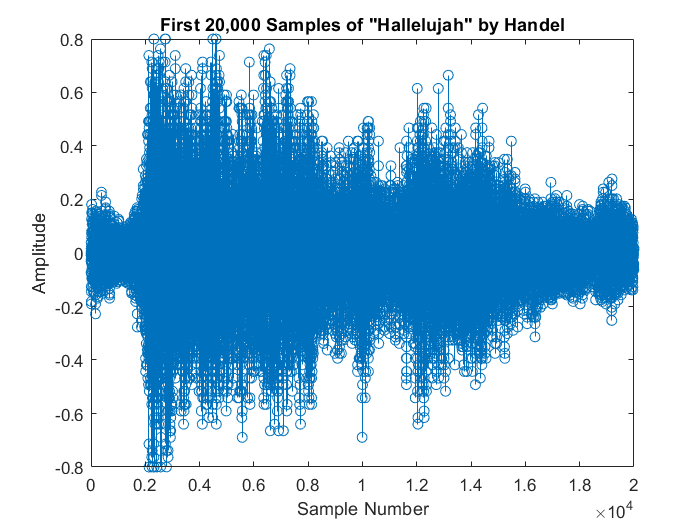

% Load the Handel music clip
load handel

% Extract the first 20,000 samples
y_20000 = y(1:20000);

% Plot the first 20,000 samples
figure;
stem(y_20000);
title('First 20,000 Samples of "Hallelujah" by Handel');
xlabel('Sample Number');
ylabel('Amplitude');

**Part 2:** Generate given signals from the frist 20,000 samples

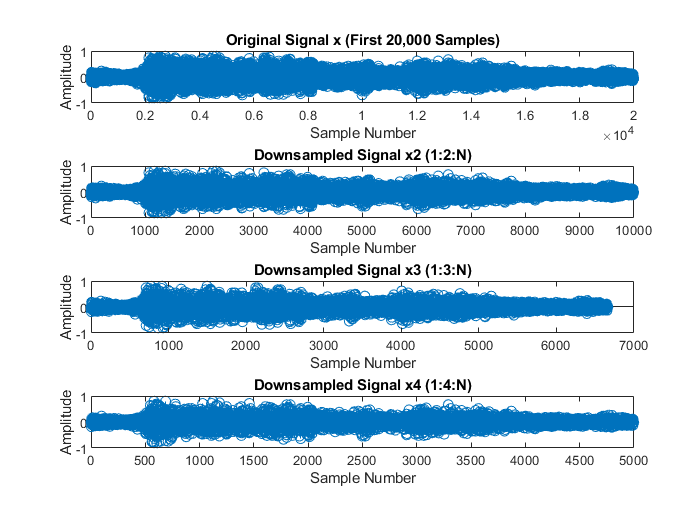

% Load the Handel music clip
load handel

% Define the number of samples
N = 20000;

% Extract the first 20,000 samples
x = y(1:N);

% Generate signals with different sampling rates
x2 = x(1:2:N); % Downsample by 2
x3 = x(1:3:N); % Downsample by 3
x4 = x(1:4:N); % Downsample by 4

% Plot the original and downsampled signals
figure;
subplot(4, 1, 1);
stem(x);
title('Original Signal x (First 20,000 Samples)');
xlabel('Sample Number');
ylabel('Amplitude');

subplot(4, 1, 2);
stem(x2);
title('Downsampled Signal x2 (1:2:N)');
xlabel('Sample Number');
ylabel('Amplitude');

subplot(4, 1, 3);
stem(x3);
title('Downsampled Signal x3 (1:3:N)');
xlabel('Sample Number');
ylabel('Amplitude');

subplot(4, 1, 4);
stem(x4);
title('Downsampled Signal x4 (1:4:N)');
xlabel('Sample Number');
ylabel('Amplitude');

**Part 3**: Apply the DFT-based method to interpolate the signals x2, x3 and x4

 *a) Interpolate the signal x2 with K = 1*

% Parameters
N = 20000;  % Number of samples

% Obtain signals
x = y(1:N);       % Original signal
x2 = x(1:2:N);    % Subsample every 2nd sample (decimated signal)

% Interpolation process for x2 with K = 1 (frequency-domain zero-padding)
K = 1;            % Upsampling factor (K = 1 means interpolating back to original rate)
% Compute FFT of x2
X2 = fft(x2);  
N2 = length(X2);  % Length of the DFT
half_N2 = N2 / 2; % Half the length of the DFT

% Split the DFT into two parts (positive and negative frequencies)
first_half = X2(1:half_N2);        % Positive frequency components
second_half = X2(half_N2+2:end);   % Negative frequency components

% Handle midpoint for even-length signals
MidTerm = X2(half_N2+1) / 2;  % Midpoint term since signal length is even

% Insert zeros for interpolation
zero_list = zeros(K*N2 - 1, 1);    % Zero padding

% Reconstruct spectrum with zero padding
X_Z = [first_half; MidTerm; zero_list; MidTerm; second_half];

% Compute inverse FFT and scale
x_interpolated = real(ifft(X_Z)) * (K+1);

% Adjust the length of the interpolated signal to match original
x_n = x_interpolated(1:(K+1)*(N2-1)+1);  % Select necessary samples

% Calculate the 2-norm difference between interpolated and original signals
len_diff = length(x) - length(x_n);

% Zero-pad the shorter signal if necessary
if len_diff > 0
    x_n = [x_n; zeros(len_diff, 1)];  % Pad interpolated signal
elseif len_diff < 0
    x_n = x_n(1:length(x));           % Truncate interpolated signal
end

% Compute the 2-norm difference
norm_diff = norm(x - x_n);  % Euclidean distance (2-norm)
disp(['2-Norm Difference: ', num2str(norm_diff)]);

2-Norm Difference: 6.1447


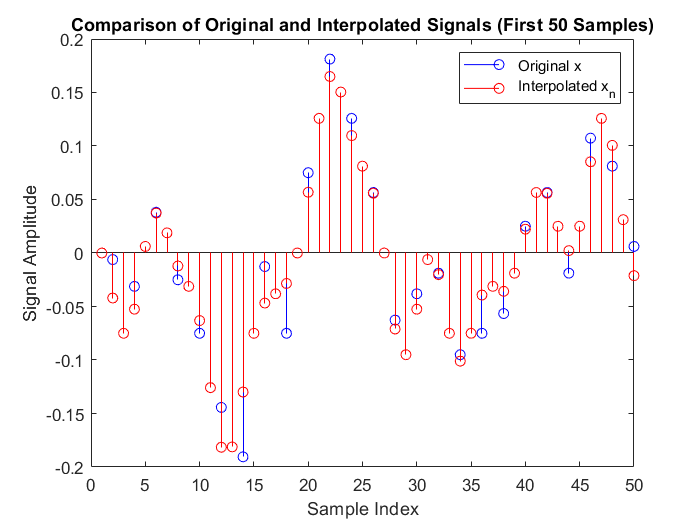


% Plot the first 50 samples of both original and interpolated signals as stem plots
figure;
stem(1:50, x(1:50), 'b', 'DisplayName', 'Original x');  % Plot original signal
hold on;
stem(1:50, x_n(1:50), 'r', 'DisplayName', 'Interpolated x_n');  % Plot interpolated signal
hold off;
legend('show');
title('Comparison of Original and Interpolated Signals (First 50 Samples)');
xlabel('Sample Index');
ylabel('Signal Amplitude');

*b) Interpolate the signal x3 with K = 2*

% Parameters
N = 20000;  % Number of samples

% Obtain signals
x = y(1:N);       % Original signal
x3 = x(1:3:N);    % Subsample every 3rd sample (decimated signal)

% Interpolation process for x3 with K = 2 (frequency-domain zero-padding)
K = 2;            % Upsampling factor (K = 2 means interpolating back to original rate)

% Compute FFT of x3
X3 = fft(x3);  
N3 = length(X3);  % Length of the DFT
half_N3 = floor(N3 / 2);  % Make sure it's an integer (half the length of the DFT)

% Split the DFT into two parts (positive and negative frequencies)
first_half = X3(1:half_N3);        % Positive frequency components
second_half = X3(half_N3+2:end);   % Negative frequency components (ensure valid indices)

% Handle midpoint for even-length signals
MidTerm = X3(half_N3+1) / 2;  % Midpoint term since signal length is even

% Insert zeros for interpolation
zero_list = zeros(K*N3 - 1, 1);    % Zero padding

% Reconstruct spectrum with zero padding
X_Z = [first_half; MidTerm; zero_list; MidTerm; second_half];

% Compute inverse FFT and scale
x_interpolated = real(ifft(X_Z)) * (K+1);

% Adjust the length of the interpolated signal to match original
x_n = x_interpolated(1:(K+1)*(N3-1)+1);  % Select necessary samples

% Calculate the 2-norm difference between interpolated and original signals
len_diff = length(x) - length(x_n);

% Zero-pad the shorter signal if necessary
if len_diff > 0
    x_n = [x_n; zeros(len_diff, 1)];  % Pad interpolated signal
elseif len_diff < 0
    x_n = x_n(1:length(x));           % Truncate interpolated signal
end

% Compute the 2-norm difference
norm_diff = norm(x - x_n);  % Euclidean distance (2-norm)
disp(['2-Norm Difference for x3: ', num2str(norm_diff)]);

2-Norm Difference for x3: 8.3653


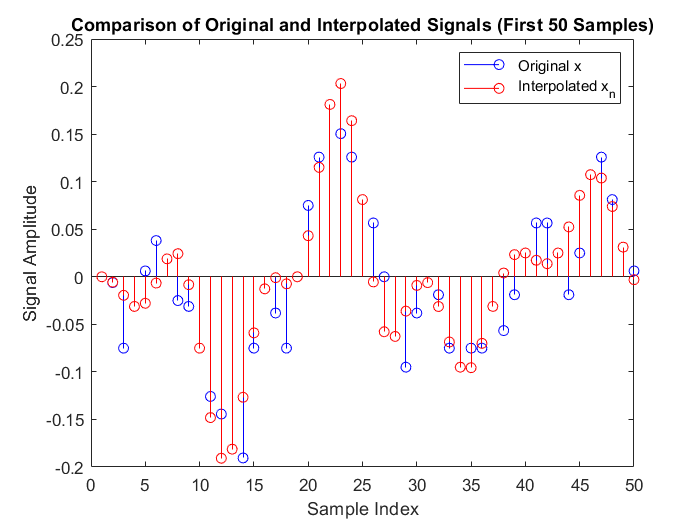



% Plot the first 50 samples of both original and interpolated signals as stem plots
figure;
stem(1:50, x(1:50), 'b', 'DisplayName', 'Original x');  % Plot original signal
hold on;
stem(1:50, x_n(1:50), 'r', 'DisplayName', 'Interpolated x_n');  % Plot interpolated signal
hold off;
legend('show');
title('Comparison of Original and Interpolated Signals (First 50 Samples)');
xlabel('Sample Index');
ylabel('Signal Amplitude');

*c) Interpolate the signal x4 with K = 3*

% Parameters
N = 20000;  % Number of samples

% Obtain signals
x = y(1:N);       % Original signal
x4 = x(1:4:N);    % Subsample every 4th sample (decimated signal)

% Interpolation process for x4 with K = 3 (frequency-domain zero-padding)
K = 3;            % Upsampling factor (K = 3 means interpolating back to original rate)

% Compute FFT of x4
X4 = fft(x4);  
N4 = length(X4);  % Length of the DFT
half_N4 = floor(N4 / 2);  % Make sure it's an integer (half the length of the DFT)

% Split the DFT into two parts (positive and negative frequencies)
first_half = X4(1:half_N4);        % Positive frequency components
second_half = X4(half_N4+2:end);   % Negative frequency components (ensure valid indices)

% Handle midpoint for even-length signals
MidTerm = X4(half_N4+1) / 2;  % Midpoint term since signal length is even

% Insert zeros for interpolation
zero_list = zeros(K*N4 - 1, 1);    % Zero padding

% Reconstruct spectrum with zero padding
X_Z = [first_half; MidTerm; zero_list; MidTerm; second_half];

% Compute inverse FFT and scale
x_interpolated = real(ifft(X_Z)) * (K+1);

% Adjust the length of the interpolated signal to match original
x_n = x_interpolated(1:(K+1)*(N4-1)+1);  % Select necessary samples

% Calculate the 2-norm difference between interpolated and original signals
len_diff = length(x) - length(x_n);

% Zero-pad the shorter signal if necessary
if len_diff > 0
    x_n = [x_n; zeros(len_diff, 1)];  % Pad interpolated signal
elseif len_diff < 0
    x_n = x_n(1:length(x));           % Truncate interpolated signal
end

% Compute the 2-norm difference
norm_diff = norm(x - x_n);  % Euclidean distance (2-norm)
disp(['2-Norm Difference for x4: ', num2str(norm_diff)]);

2-Norm Difference for x4: 23.4998


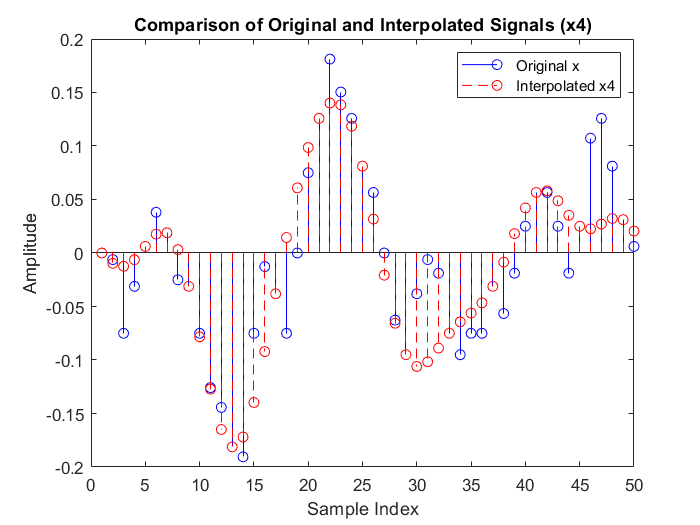


% Plot the first 50 samples of both original and interpolated signals
figure;
stem(1:50, x(1:50), 'b', 'DisplayName', 'Original x');  % Plot original signal
hold on;
stem(1:50, x_n(1:50), 'r--', 'DisplayName', 'Interpolated x4');  % Plot interpolated signal
legend;
title('Comparison of Original and Interpolated Signals (x4)');
xlabel('Sample Index');
ylabel('Amplitude');
hold off;